# Problem 1

Sampling a Periodic Signal: Write a MATLAB code to generate a sinusoid signal with an amplitude of 1 a.u. (arbitrary unit) and frequency of 0.5 Hz. Plot the analog signal as a function of time. Sample the signal with a sampling time, 𝑇𝑠 of 0.1 second. Plot the sampled signal, 𝑥[𝑛] as a function of sample number, n. [repeat question from assignment 1]

(4 points) Generate a noise signal using ‘rand’ function in MATLAB within the range [-0.5,0.5].

Plot the noise signal.

(4 Points) Add the noise to 𝑥[𝑛] to generate a noisy signal, 𝑥𝑛𝑜𝑖𝑠𝑒[𝑛].

(9 Points) Apply a moving average transformation on 𝑥𝑛𝑜𝑖𝑠𝑒[𝑛], with a symmetric window when

(i) window size=3 samples (M1 = 1, M2=1)

(ii) window size=5 samples (M1 = 2, M2=2)

(iii) window size=7 samples (M1 = 3, M2=3)

Comment on the optimal window size that recovers the trend of the original signal.

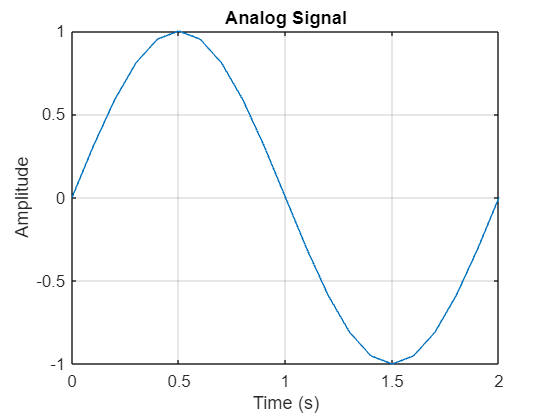

clear
clc
% Parameters
A = 1;  % Amplitude in arbitrary units
f = 0.5;  % Frequency in Hz
w = f*2*pi; % Angular frequency
Ts = 0.1; % Sampling Period
N = (2*pi)/(w*Ts);
T = 1/f; % Period

% Generate sinusoid signal
t = 0:0.1:T;
signal = A*sin(w*t);

% Generate sinusoid signal
n = 0:N-1;
t_sampled = n*Ts;
sampled_signal = A*sin(w*t_sampled);

% Generate noise signal
noise_signal = (rand(1, length(n)) - 0.5);

% Add the original signal to the noise signal
x_noise = sampled_signal + noise_signal;

% Moving Average for a window size of 3, 5, and 7
window_3_output = movmean(x_noise, 3);
window_5_output = movmean(x_noise, 5);
window_7_output = movmean(x_noise, 7);

% Plot the original analog signal
figure(1);
plot(t, signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Analog Signal');
grid on;

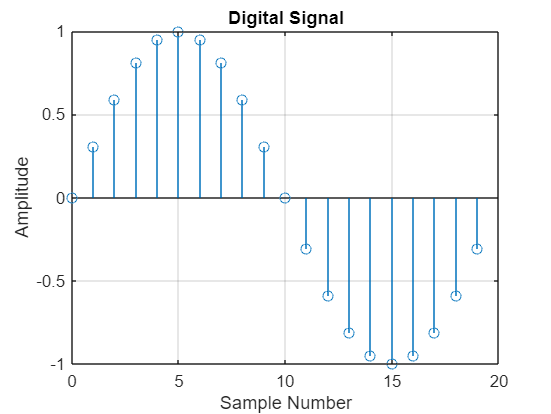


% Plot the original digital signal
figure(2);
stem(n, sampled_signal, 'Marker', 'o');
xlabel('Sample Number');
ylabel('Amplitude');
title('Digital Signal');
grid on;

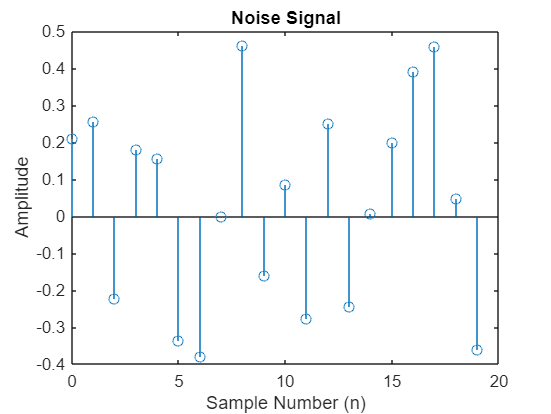


% Plot the noise signal
figure(3);
stem(n, noise_signal);
title('Noise Signal');
xlabel('Sample Number (n)');
ylabel('Amplitude');

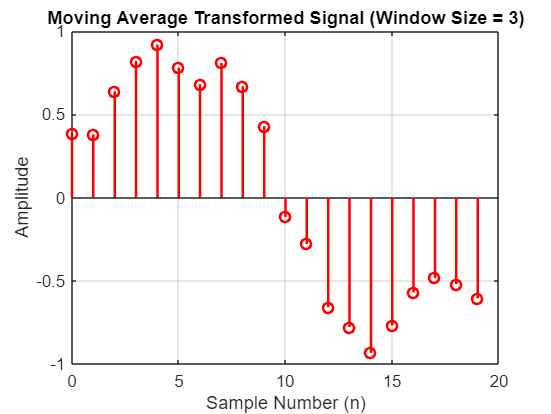


% Plot the moving avg for a window of 3
figure(4);
stem(n, window_3_output, 'r', 'LineWidth', 1.5);
title('Moving Average Transformed Signal (Window Size = 3)');
xlabel('Sample Number (n)');
ylabel('Amplitude');
grid on;

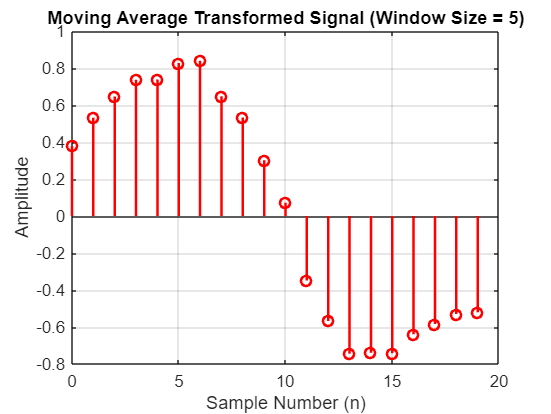


% Plot the moving avg for a window of 5
figure(5);
stem(n, window_5_output, 'r', 'LineWidth', 1.5);
title('Moving Average Transformed Signal (Window Size = 5)');
xlabel('Sample Number (n)');
ylabel('Amplitude');
grid on;

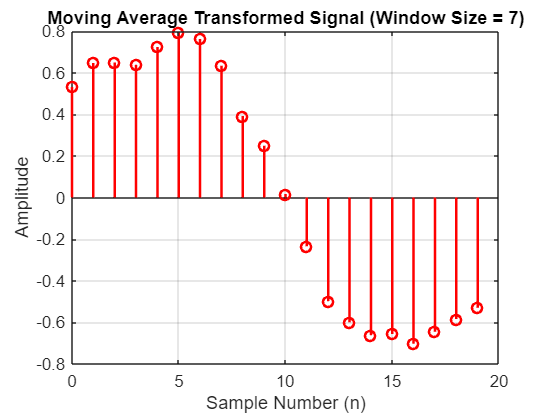


% Plot the moving avg for a window of 7
figure(6);
stem(n, window_7_output, 'r', 'LineWidth', 1.5);
title('Moving Average Transformed Signal (Window Size = 7)');
xlabel('Sample Number (n)');
ylabel('Amplitude');
grid on;